clear;


# Lab 1

#### First, let's read the data from the three different tracks.

[Y1, FS1] = audioread('Songs/melody_1.wav');
[Y2, FS2] = audioread('Songs/melody_2.wav');
[Y3, FS3] = audioread('Songs/melody_3.wav');

#### Then, set the length of the window, 0.03 is default.


lengthOfWindow = 0.03

lengthOfWindow = 0.0300

#### Use the data yielded from audioread and extract the 3 features

- Pitch: frIseq(1,:) 80 - 1100 Hz

- Correlation coefficient ($$\rho$$): frIseq(2,:) 

- Esitmates of per-sample intensity: frIseq(3,:)

frIseqT1 = GetMusicFeatures(Y1,FS1,lengthOfWindow);
frIseqT2 = GetMusicFeatures(Y2,FS2,lengthOfWindow);
frIseqT3 = GetMusicFeatures(Y3,FS3,lengthOfWindow);


#### Plot the frequencies for the three different signals. Note that two melodies are from the same song and should thus be similair.

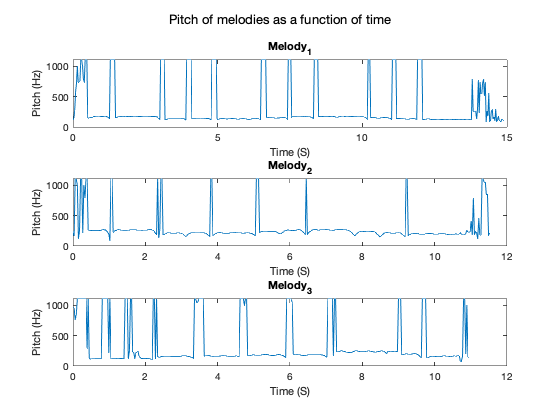


figure;
sgtitle('Pitch of melodies as a function of time');
subplot(3,1,1);
t_1 = 0.00:lengthOfWindow:(length(frIseqT1(1,:))-1)*0.03;
plot(t_1, frIseqT1(1,:));
xlabel('Time (S)');
ylabel('Pitch (Hz)');
title('Melody_1')

subplot(3,1,2);
t_2 = 0.00:lengthOfWindow:(length(frIseqT2(1,:))-1)*0.03;
plot(t_2, frIseqT2(1,:));
xlabel('Time (S)');
ylabel('Pitch (Hz)');
title('Melody_2')

subplot(3,1,3);
t_3 = 0.00:lengthOfWindow:(length(frIseqT3(1,:))-1)*0.03;
plot(t_3, frIseqT3(1,:));
xlabel('Time (S)');
ylabel('Pitch (Hz)');

title('Melody_3')

#### Let's now plot the per-sample intensity, note that the time is still the same as the above figure.

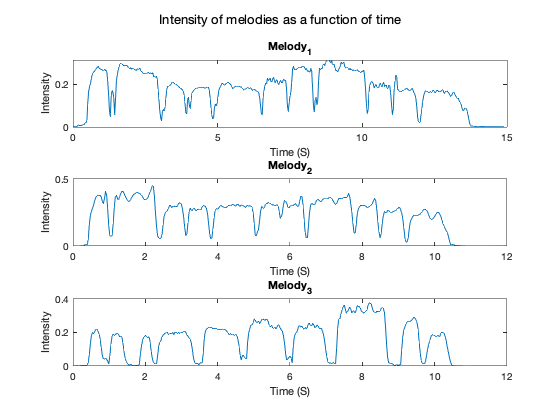


figure;
sgtitle('Intensity of melodies as a function of time');
subplot(3,1,1);
plot(t_1, frIseqT1(3,:));
xlabel('Time (S)');
ylabel('Intensity');
title('Melody_1')

subplot(3,1,2);
plot(t_2, frIseqT2(3,:));
xlabel('Time (S)');
ylabel('Intensity');
title('Melody_2')

subplot(3,1,3);
plot(t_3, frIseqT3(3,:));
xlabel('Time (S)');
ylabel('Intensity');

title('Melody_3')